%% 4번 문제
clear; clc;

rng('default');

lambda_order = 180;
days = 365;

daily_orders = zeros(days, 1);
for d = 1:days
    time_sum = 0;
    count = 0;
    while true
       
        time_sum = time_sum + (-log(rand) / lambda_order);
        if time_sum > 1
            break;
        end
        count = count + 1;
    end
    daily_orders(d) = count;
end

% (b) 
daily_total_times = zeros(days, 1);

for d = 1:days
    num_orders = daily_orders(d);
    if num_orders > 0
        % 해당 날짜의 주문 수만큼 처리 시간 생성
        times = 6 + 2 * randn(num_orders, 1);
        % 음수 처리 시간은 0분으로 변경
        times(times < 0) = 0;
        % 하루 총 처리 시간 합산
        daily_total_times(d) = sum(times);
    else
        daily_total_times(d) = 0;
    end
end

% (c) 
overtime_ratio = mean(daily_total_times > 1200);
fprintf('=== 4번 결과 ===\n');

=== 4번 결과 ===


fprintf('하루 총 처리 시간이 1200분을 초과하는 날의 비율: %.2f%%\n', overtime_ratio * 100);

하루 총 처리 시간이 1200분을 초과하는 날의 비율: 8.22%


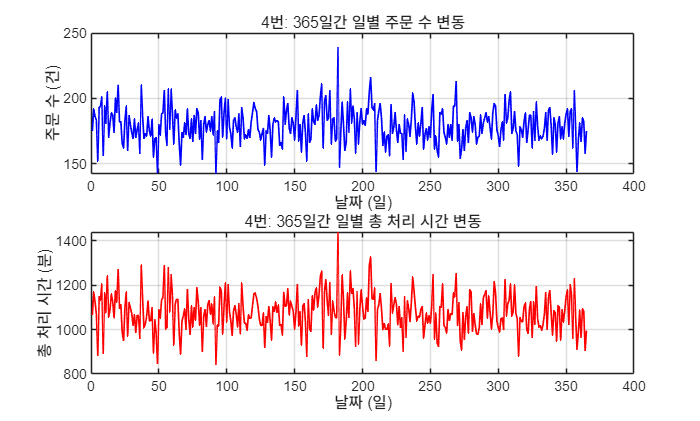


% (d) 
figure(4);
subplot(2,1,1);
plot(1:days, daily_orders, 'b-', 'LineWidth', 1);
title('4번: 365일간 일별 주문 수 변동');
xlabel('날짜 (일)'); ylabel('주문 수 (건)');
grid on;

subplot(2,1,2);
plot(1:days, daily_total_times, 'r-', 'LineWidth', 1);
title('4번: 365일간 일별 총 처리 시간 변동');
xlabel('날짜 (일)'); ylabel('총 처리 시간 (분)');
grid on;

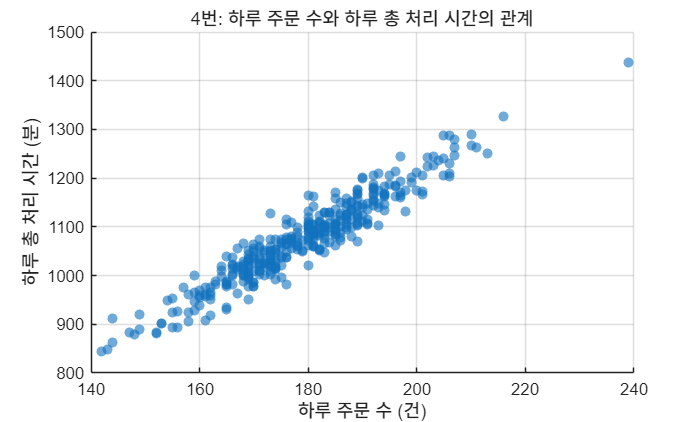


% (e) 
figure(5);
scatter(daily_orders, daily_total_times, 'filled', 'MarkerFaceAlpha', 0.6);
title('4번: 하루 주문 수와 하루 총 처리 시간의 관계');
xlabel('하루 주문 수 (건)');
ylabel('하루 총 처리 시간 (분)');
grid on;